# Temperature Control

## Simulink Model

open_system('shower')

## Fuzzy Inference System

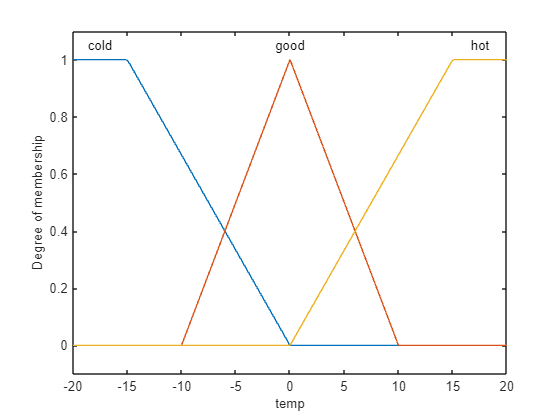

figure
plotmf(fis,'input',1)

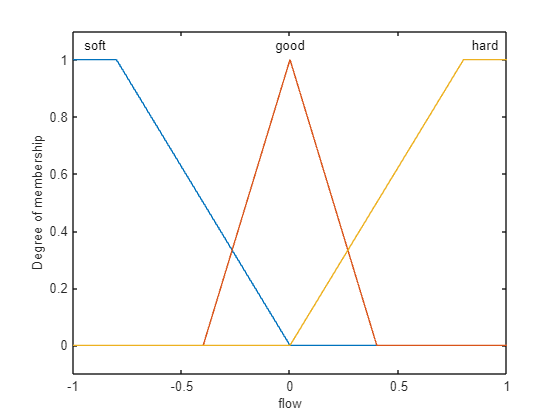

figure
plotmf(fis,'input',2)

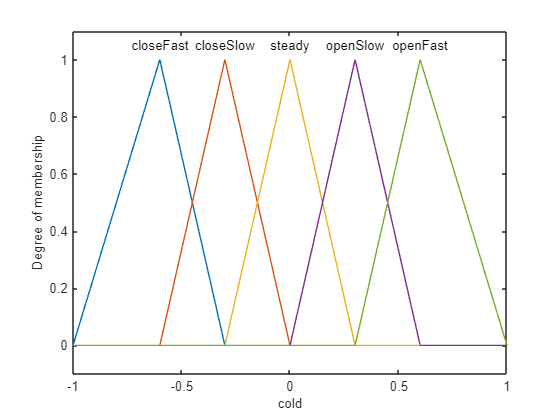

figure
plotmf(fis,'output',1)

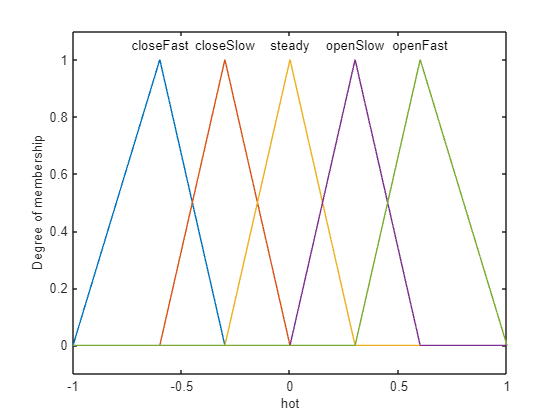

figure
plotmf(fis,'output',2)

fis.Rules

ans =   1×9 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                                  Description                          
         ______________________________________________________________

    1    "temp==cold & flow==soft => cold=openSlow, hot=openFast (1)"  
    2    "temp==cold & flow==good => cold=closeSlow, hot=openSlow (1)" 
    3    "temp==cold & flow==hard => cold=closeFast, hot=closeSlow (1)"
    4    "temp==good & flow==soft => cold=openSlow, hot=openSlow (1)"  
    5    "temp==good & flow==good => cold=steady, hot=steady (1)"      
    6    "temp==good & flow==hard => cold=closeSlow, hot=closeSlow (1)"
    7    "temp==hot & flow==soft => cold=openFast, hot=openSlow (1)"   
   

## Simulation

The model simulates the controller with periodic changes in the setpoints of the water temperature and flow rate.

set_param('shower/flow scope','Open','on','Ymin','0','Ymax','1')
set_param('shower/temp scope','Open','on','Ymin','15','Ymax','30')
sim('shower',50)